clear all;

s = tf('s');
L = (s+7)/(s*(s+5)*(s+15)*(s+20));
figure(1)
rlocus(L)
axis([-22 2 -15 15])

zeta = 0.7

zeta = 0.7000

wn = 1.8

wn = 1.8000

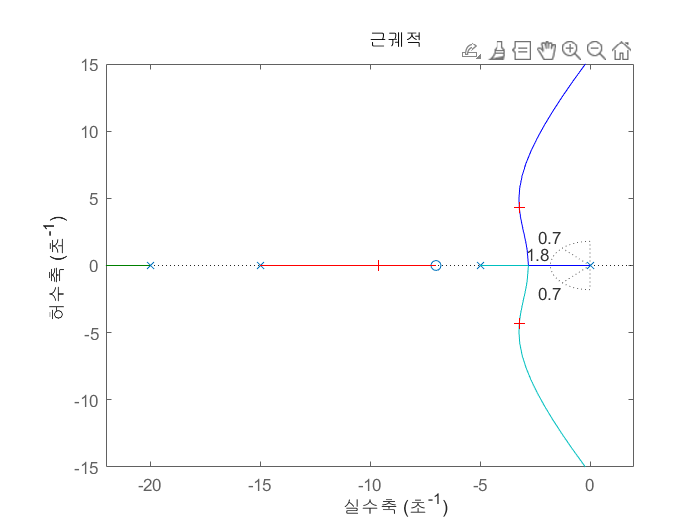

Select a point in the graphics window


selected_point = -3.2045 + 4.3176i

k = 952.6840

poles =  -23.9660 + 0.0000i
  -9.6036 + 0.0000i
  -3.2152 + 4.3171i
  -3.2152 - 4.3171i



sgrid(zeta,wn)
[k, poles] = rlocfind(L)

k

k = 952.6840

poles

poles =  -23.9660 + 0.0000i
  -9.6036 + 0.0000i
  -3.2152 + 4.3171i
  -3.2152 - 4.3171i



T = feedback(k*L,1)

T =
 
              952.7 s + 6669
  --------------------------------------
  s^4 + 40 s^3 + 475 s^2 + 2453 s + 6669
 
연속시간 전달 함수입니다.
모델 속성


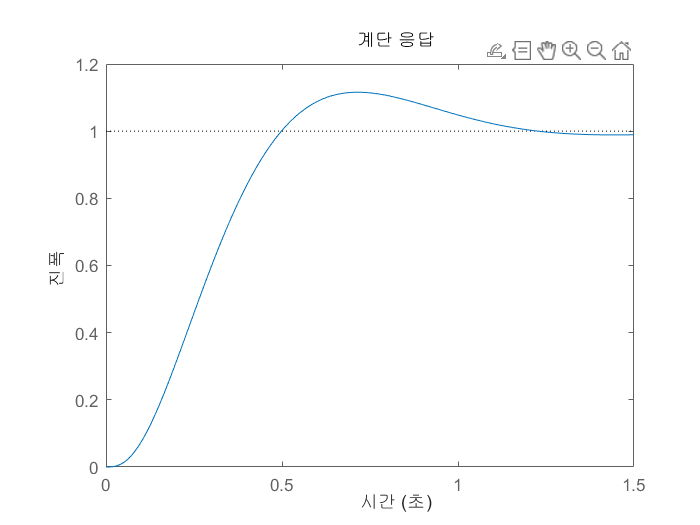

figure(3)
step(T)

stepinfo(T)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.3181
    TransientTime: 1.1091
     SettlingTime: 1.1091
      SettlingMin: 0.9165
      SettlingMax: 1.1159
        Overshoot: 11.5942
       Undershoot: 0
             Peak: 1.1159
         PeakTime: 0.7193


k =770

k = 770

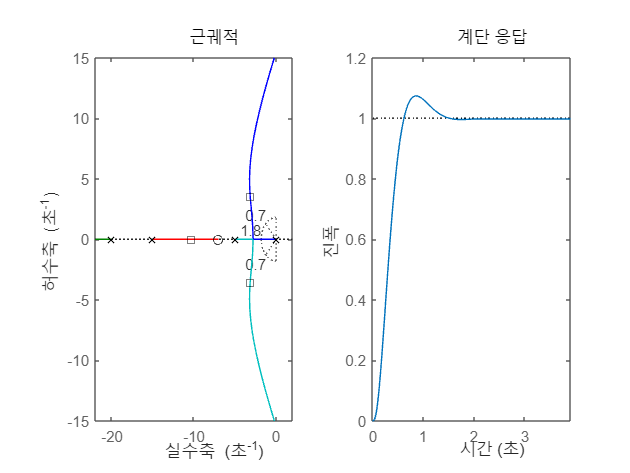



figure(4)
subplot(1,2,2)
subplot(1,2,1)
rlocus(L)
hold on
rlocus(L,k,'ks')
hold off
axis([-22 2 -15 15])
sgrid(zeta,wn)
subplot(1,2,2)
step(feedback(L*k,1))
axis([0 3.9 0 1.2])